% AMPLIACION DE ROBOTICA
% PRACTICA 4: Navegacion local con campos potenciales
% Evitar obstaculos

clc
clearvars
clear all
close all


% Este archivo contiene los nodos y costes del mapa2

nodos = [
1,3,146;
2,34,127;
3,49,117;
4,49,141;
5,60,134;
6,83,146;
7,81,106;
8,95,120;
9,95,138;
10,123,137;
11,123,146;
12,142,146;
13,130,129;
14,130,115;
15,109,115;
16,5,112;
17,4,35;
18,16,28;
19,40,18;
20,49,34;
21,71,27;
22,52,18;
23,71,47;
24,92,47;
25,97,4;
26,105,58;
27,112,4;
28,120,58;
29,127,4;
30,135,58;
31,142,4;
32,146,63;
33,129,67;
34,77,64;
35,46,67;
36,16,67;
37,17,112;
38,48,101;
39,56,106;
40,85,86;
41,113,85;
42,125,89;
43,129,104;
44,132,89;
45,146,85;
46,132,83;
47,125,83;
48,23,7;
49,70,7
]

nodos =      1     3   146
     2    34   127
     3    49   117
     4    49   141
     5    60   134
     6    83   146
     7    81   106
     8    95   120
     9    95   138
    10   123   137



costes = [
0, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
3, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 1, 0, 1, 2, 0, 2, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 2, 0, 0, 3, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 3, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 2, 0, 3, 1, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 3, 3, 2, 0, 0, 1, 0, 0, 0, 0, 0, 0;
0, 0, 3, 0, 0, 0, 1, 0, 2, 0, 0, 0, 0, 0, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 2, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 3, 0, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 3, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 3, 0, 0, 0, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 3, 0, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 3, 0, 0, 0, 0, 0, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 2, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 3, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 0, 2, 0, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 2, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 3, 1, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 1, 0, 0, 0, 0, 0, 0, 1, 0, 0, 0, 1, 2, 2, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 1, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 3, 0, 0, 0, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 3, 0, 1, 0, 0, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 3, 0, 1, 3, 1, 0, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 3, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 1, 0, 0, 0, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 3, 0, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 3, 0, 0, 0, 3, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 2, 0, 2, 1, 0, 0, 0, 2, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 2, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 2, 0, 2, 1, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 2, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 2, 0, 2, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 2, 0, 0, 0, 0, 0, 0, 0, 2, 0, 0, 0, 0, 0, 0, 0, 0;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1;
0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0
]

costes =      0     3     0     0     0     0     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     3     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     1     2     0     2     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0    


[fil,col]=size(costes)

fil = 49

col = 49

H=zeros(fil,col)

H =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

maximo=0;
minimo=300;
for i=1:fil
    for j=1:col
        H(i,j)=sqrt((nodos(i,2)-nodos(j,2))^2 + (nodos(i,3)-nodos(j,3))^2);
        if (H(i,j)>maximo)
            maximo=H(i,j);
        end
        if (H(i,j)<minimo && H(i,j)>0)
            minimo=H(i,j);
        end
    end
end
H

H =          0   36.3593   54.3783   46.2709   58.2495   80.0000   87.6584   95.6033   92.3472  120.3370  120.0000  139.0000  128.1327  130.7287  110.4400   34.0588  111.0045  118.7139  133.2404  121.0785  137.0584  137.0584  120.1041  133.1240  170.2939  134.7145  179.0112  146.4001  188.5206  158.6443  198.7083  165.3421  148.7179  110.4536   89.9444   80.0625   36.7696   63.6396   66.4003  101.6071  125.7816  134.6588  132.8157  141.0319  155.4670  143.5618  137.3062  140.4315  154.3049
   36.3593         0   18.0278   20.5183   26.9258   52.5547   51.4782   61.4003   61.9839   89.5600   91.0055  109.6586   96.0208   96.7471   75.9539   32.6497   96.7678  100.6231  109.1650   94.2019  106.6255  110.4762   88.1419   98.8130  138.1955   99.0051  145.6468  110.2588  154.2012  122.3193  163.6857  128.9961  112.3610   76.2758   61.1882   62.6418   22.6716   29.5296   30.4138   65.4370   89.4707   98.6154   97.7446  105.1095  119.6161  107.4244  101.0792  120.5031  125.2837
   54.3783   1

maximo

maximo = 198.7083

minimo

minimo = 6

for i=1:fil
    for j=1:col
        if costes(i,j)~=0
            costes(i,j)=sqrt((nodos(i,2)-nodos(j,2))^2 + (nodos(i,3)-nodos(j,3))^2);

          
        end

    end
end
costes

costes =          0   36.3593         0         0         0         0         0         0         0         0         0         0         0         0         0   34.0588         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   36.3593         0   18.0278         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         

## Carga del mapa de ocupacion

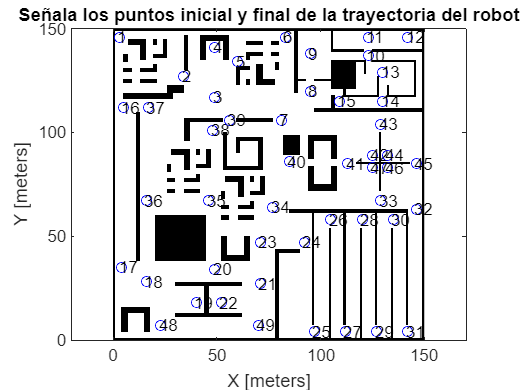

map_img=imread('mapa2.pgm');
map_neg=imcomplement(map_img);
map_bin=imbinarize(map_neg);
mapa=binaryOccupancyMap(map_bin);

figure; 
show(mapa);  % Mostrar el mapa
hold on;
axis equal;

% Marcar los puntos de inicio y destino

title('Señala los puntos inicial y final de la trayectoria del robot');
for i=1:length(nodos)
    plot(nodos(i,2),nodos(i,3),'bo')
    if nodos(1,1)>9
        offset=2;
    else
        offset=1;
    end
    text(nodos(i,2)-offset,nodos(i,3),int2str(nodos(i,1)))
end

% Configuracion del sensor (laser de barrido)
max_rango=10;
angulos=-pi/2:(pi/180):pi/2; % resolucion angular barrido laser

% Caracteristicas del vehiculo y parametros del metodo
v=0.4;            % Velocidad del robot
D=1.5;           % Rango del efecto del campo de repulsión de los obstáculos
alfa=10000;           % Coeficiente de la componente de atracción
beta=100;      % Coeficiente de la componente de repulsión

## Inicialización

prompt1 = "Introduce el nodo desde el que partes: ";
inicio = input(prompt1)

inicio = 48

prompt2 = "Introduce el nodo al que deseas llegar: ";
fin = input(prompt2)

fin = 45

prompt3= "Introduce 1 si quieres calcularlo mediante Dijkstra\n Introduce cualquier otro si quieres calcularlo mediante A*\n";
opcion = input(prompt3)

if opcion==1
    fprintf("Dijkstra\n")

Dijkstra


    %tic
    [cuesta,ruta]=dijkstra(costes,inicio,fin)

cuesta = 176.1039

ruta =     48    18    20    23    34    33    45


    %toc

Elapsed time is 0.140033 seconds.


    
else
    fprintf("A*\n")

A*


    %tic
    [cuesta,ruta]=Aestrella(costes, H, inicio, fin)

cuesta = 176.1039

ruta =     48    18    20    23    34    33    45


    %toc

Elapsed time is 0.056042 seconds.


Destino alcanzado.
Destino alcanzado.
Destino alcanzado.
Destino alcanzado.
Destino alcanzado.
Destino alcanzado.


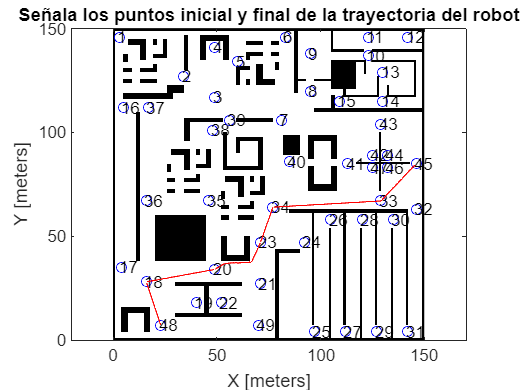

end

%ruta va a ser un vector longitud fil=1, colum=tamaño real
[fil,col]=size(ruta);
ang=0;    % El robot empieza en la posición de origen (orientacion cero)
path = [];                 % Se almacena el camino recorrido
[fil1,col1]=size(nodos);
for j=1:(col-1)
    nodo_origen=ruta(1,j);
    nodo_destino=ruta(1,j+1);
    [fil1,col1]=size(nodos);
    n=0;
    i=1;
    while i<=fil1 && n<2
        if nodos(i,1) == nodo_origen
            origen=[nodos(i,2),nodos(i,3)];
            n=n+1;
        end
        if nodos(i,1) == nodo_destino
            destino=[nodos(i,2),nodos(i,3)];
            n=n+1;
        end
        i=i+1;
    end
    robot = [origen(1), origen(2), ang];
     % Se añade al camino la posicion actual del robot
    iteracion=0;
    [ang,realizado]=campos_potenciales(robot,destino,path,v,iteracion,mapa,alfa,beta,D,max_rango,angulos);
    if (realizado==false)
        break;
    end
    
end

## Calculo de la trayectoria

function [angulo,realizado]=campos_potenciales(robot,destino,path,v,iteracion,mapa,alfa,beta,D,max_rango,angulos)
    while norm(destino-robot(1:2)) > v && iteracion<1000    % Hasta menos de una iteración de la meta (10 cm)
    % TU CODIGO AQUI %%%%%%%%%%%%%
    % Cálculo de la fuerza de atracción
    dir_atrac = destino - robot(1:2);
    Fatrac = alfa * dir_atrac / norm(dir_atrac);  % Normalizar el vector de atracción

    % Simulación del sensor Lidar
    obs = SimulaLidar(robot, mapa, angulos, max_rango);
    
    % Inicializar la fuerza de repulsión
    Frepul = [0, 0];

    % Procesar cada obstáculo detectado
    for i = 1:size(obs, 1)
        if ~isnan(obs(i,1))  % Si hay detección de obstáculo
            dir_repul = robot(1:2) - obs(i, :);
            pobs = norm(dir_repul);
            if pobs <= D
                Frepul = Frepul + ((beta*dir_repul)/ (pobs^2 ));
            end
        end
    end

    % Cálculo de la fuerza resultante
    Fres = Fatrac + Frepul;

    % Nueva orientación del robot
    orientacion = atan2(Fres(2), Fres(1));

    robot(1:2) = robot(1:2)+ v * [cos(orientacion), sin(orientacion)];
    robot(3) = orientacion;
    angulo=robot(3);
    
    
    
    
    path = [path;robot];	% Se añade la nueva posición al camino seguido
    
    plot(path(:,1), path(:,2), '-r');
    hold on;
    drawnow;
    
    iteracion=iteracion+1;
    end


if iteracion==1000   % Se ha caído en un mínimo local
    fprintf('No se ha podido llegar al destino.\n')
    realizado=false;
else
    fprintf('Destino alcanzado.\n')
    realizado=true;
    
end
end

## funcion para simular el sensor

function [obs]=SimulaLidar(robot, mapa, angulos, max_rango)
obs=rayIntersection(mapa,robot,angulos, max_rango);
% plot(obs(:,1),obs(:,2),'*r') % Puntos de interseccion lidar
% plot(robot(1),robot(2),'ob') % Posicion del robot
% for i = 1:length(angulos)
%     plot([robot(1),obs(i,1)],...
%         [robot(2),obs(i,2)],'-b') % Rayos de interseccion
% end
% % plot([robot(1),robot(1)-6*sin(angulos(4))],...
% %     [robot(2),robot(2)+6*cos(angulos(4))],'-b') % Rayos fuera de
% %     rango
end

funcion dijkstra

function [coste, ruta] = dijkstra(G, a, b)
    % Se obtiene el tamaño de la matriz de adyacencia G
    [fil, col] = size(G);
    
    % Se inicializa la matriz C con el nodo de inicio
    C = [a, a, 0];
    B = []; % Matriz para almacenar los nodos visitados
    e = a;
    D=G;
    coste=0;
    while C(1,1) ~= b
        for i = 1:fil
            if D(e, i) ~= 0  % Si hay conexión entre los nodos
                C = [C; i, e, G(e, i) + C(1,3)];
                D(e,i)=0;
                D(i,e)=0;
            end
        end
        
        % Se guarda la primera fila en B y se elimina de C
        B = [B; C(1,:)];
        C(1, :) = [];
        
        % Ordenar C por la tercera columna (coste acumulado)
        C = sortrows(C, 3);
        
        % Se selecciona el siguiente nodo a visitar
        if isempty(C)
            %error('No hay ruta posible entre %d y %d', a, b);
            coste=inf;
            ruta=[];
            break;
        end
        e = C(1, 1);
    end
    if (coste~=inf)
    B = [B; C(1,:)];
    % Construcción de la ruta óptima
    [fil, ~] = size(B);
    f = b;
    ruta = b;
    coste = B(fil,3);
    i=1;
    
    
    
        while i<=fil
            if B(i,1)==f
                f=B(i,2);%se cambia el valor de f
                ruta2=ruta;
                ruta=[f,ruta2];
                i=1;
            end
            if ruta(1)==B(1,1) %solo se debe dar en el principio
                i=fil+1;
            end
            i=i+1;

        end
        
    
    end
end
function [coste, ruta] = Aestrella(G,H, a, b)
    % Se obtiene el tamaño de la matriz de adyacencia G
    [fil, col] = size(G);
    
    % Se inicializa la matriz C con el nodo de inicio
    C = [a, a, G(a,a), H(a,a)];
    B = []; % Matriz para almacenar los nodos visitados
    e = a;
    D=G;
    coste=0;
    while C(1,1) ~= b
        for i = 1:fil
            if D(e, i) ~= 0  % Si hay conexión entre los nodos
                C = [C; i, e, G(e, i) + C(1,3),H(e,i)+C(1,4)];
                D(e,i)=0;
                D(i,e)=0;
            end
        end
        
        % Se guarda la primera fila en B y se elimina de C
        B = [B; C(1,:)];
        C(1, :) = [];
        
        % Ordenar C por la tercera columna (coste acumulado)
        C = sortrows(C, 3);
        C = sortrows(C, 4);
        
        % Se selecciona el siguiente nodo a visitar
        if isempty(C)
            %error('No hay ruta posible entre %d y %d', a, b);
            coste=inf;
            ruta=[];
            break;
        end
        e = C(1, 1);
    end
    if (coste~=inf)
    B = [B; C(1,:)];
    % Construcción de la ruta óptima
    [fil, ~] = size(B);
    f = b;
    ruta = b;
    coste = B(fil,3);
    i=1;
    
    
    
        while i<=fil
            if B(i,1)==f
                f=B(i,2);%se cambia el valor de f
                ruta2=ruta;
                ruta=[f,ruta2];
                i=1;
            end
            if ruta(1)==B(1,1) %solo se debe dar en el principio
                i=fil+1;
            end
            i=i+1;

        end
        
    
    end
end

